# Práctica 1 - Cortocircuitos I - Apartado A

## Sistemas Eléctricos y de Potencia

Pablo García Peris - 53310

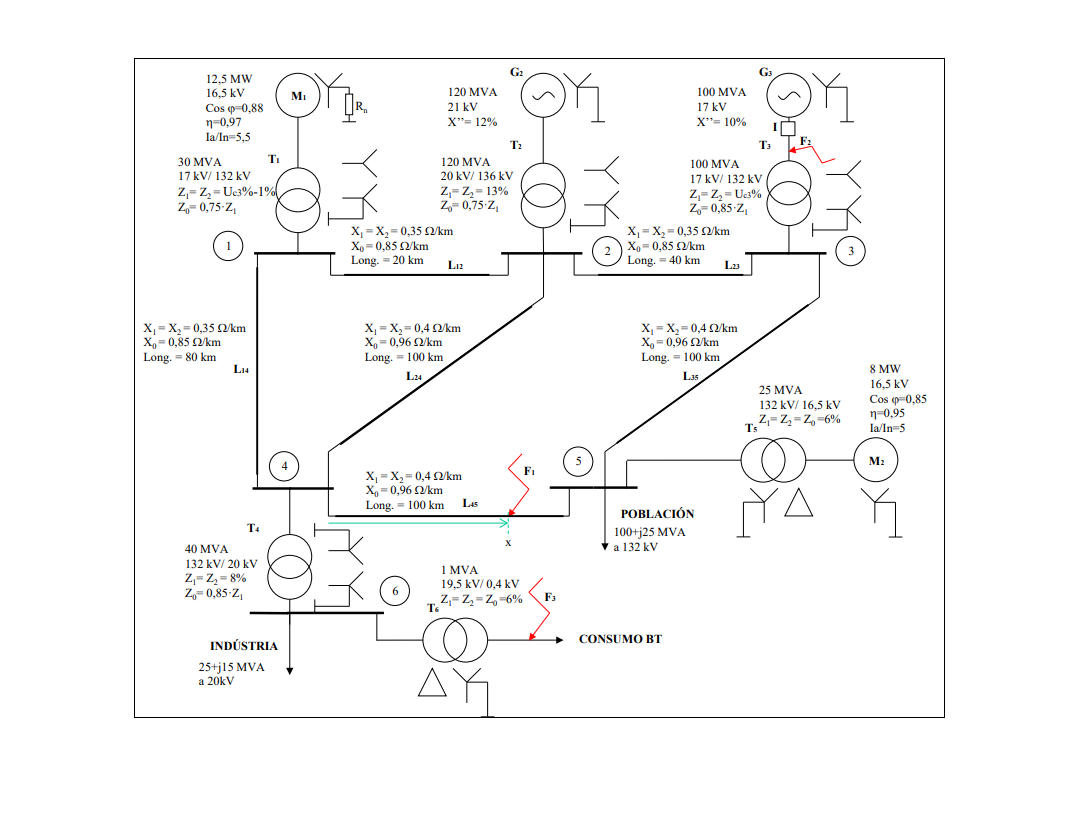

clear
clc
format shortG

imshow('Enunciado.png');

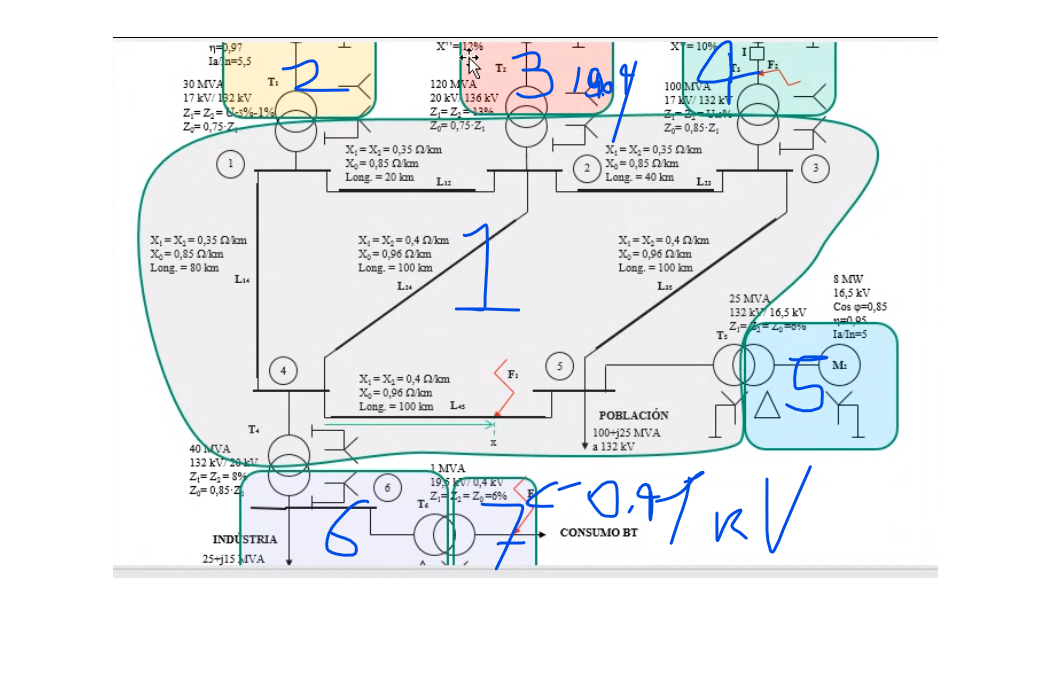

imshow('Zonas.png');

## Definición de constantes

% Unidades
k = 1e3;
M = 1e6;

Sbase = 100*M;

% Nº de matrícula
Nmatricula = 53310;
Uc3 = 2*Nmatricula*1e-4;

## Zona2

% Valores base
Ubase2 = 17*k;
Zbase2 = Ubase2^2/Sbase

Zbase2 =          2.89



% Motor 1
PnM1 = 12.5*M;
UnM1 = 16.5*k;
cosphiM1 = 0.88;
rendM1 = 0.97;
IaInM1 = 5.5;

SnM1 = PnM1/(cosphiM1*rendM1);
ZM1 = 1/IaInM1*UnM1^2/SnM1;
ZM1pu(1) = ZM1/Zbase2*1j;
ZM1pu(2) = ZM1pu(1);
ZM1pu(3) = ZM1pu(1)

ZM1pu =             0 +     1.1696i            0 +     1.1696i            0 +     1.1696i



% Trafo 1
SnT1 = 30*M;
UnT1 = 17*k;
ZccT1pu = (Uc3 - 1)/100;

ZT1 = ZccT1pu*UnT1^2/SnT1;
ZT1pu(1) = ZT1/Zbase2*1j;
ZT1pu(2) = ZT1pu(1);
ZT1pu(3) = 0.75*ZT1pu(1)

ZT1pu =             0 +    0.32207i            0 +    0.32207i            0 +    0.24155i



% Puesta a tierra del motor
Rn = Nmatricula*1e-5;

Rnpu(1) = 0;
Rnpu(2) = 0;
Rnpu(3) = 3*Rn/Zbase2

Rnpu =             0            0      0.55339


## Zona 3

% Valores base
Ubase3 = 132*k*20/136

Ubase3 =         19412


Zbase3 = Ubase3^2/Sbase;

% Generador 2
SnG2 =  120*M;
UnG2 = 21*k;
XG2pu = 0.12;

XG2 = XG2pu*UnG2^2/SnG2/Zbase3;
ZG2pu(1) = XG2pu*1j;
ZG2pu(2) = ZG2pu(1);
ZG2pu(3) = ZG2pu(1)

ZG2pu =             0 +       0.12i            0 +       0.12i            0 +       0.12i



% Trafo 2
SnT2 = 120*M;
UnT2 = 20*k;
ZccT2pu = 0.13;

ZT2 = ZccT2pu*UnT2^2/SnT2;
ZT2pu(1) = ZT2/Zbase3*1j;
ZT2pu(2) = ZT2pu(1);
ZT2pu(3) = 0.75*ZT2pu(1)

ZT2pu =             0 +      0.115i            0 +      0.115i            0 +   0.086249i


## Zona 4

% Valores base
Ubase4 = 17*k;
Zbase4 = Ubase4^2/Sbase;

% Generador 3
SnG3 =  100*M;
UnG3 = 17*k;
XG3pu = 0.1;

XG3 = XG3pu*UnG3^2/SnG3/Zbase4;
ZG3pu(1) = XG3pu*1j;
ZG3pu(2) = ZG3pu(1);
ZG3pu(3) = ZG3pu(1)

ZG3pu =             0 +        0.1i            0 +        0.1i            0 +        0.1i



% Trafo 3
SnT3 = 100*M;
UnT3 = 17*k;
ZccT3pu = Uc3/100;

ZT3 = ZccT3pu*UnT3^2/SnT3;
ZT3pu(1) = ZT3/Zbase4*1j;
ZT3pu(2) = ZT3pu(1);
ZT3pu(3) = 0.85*ZT3pu(1)

ZT3pu =             0 +    0.10662i            0 +    0.10662i            0 +   0.090627i
